# Newtons 2. lov, retlinet

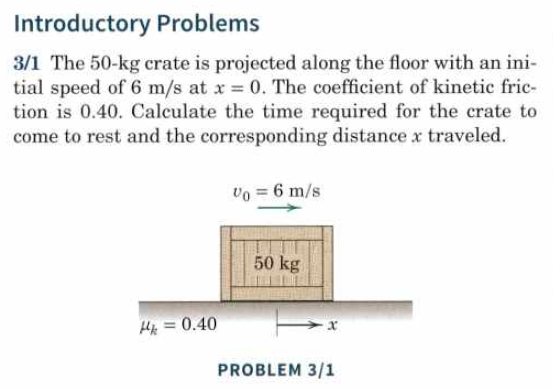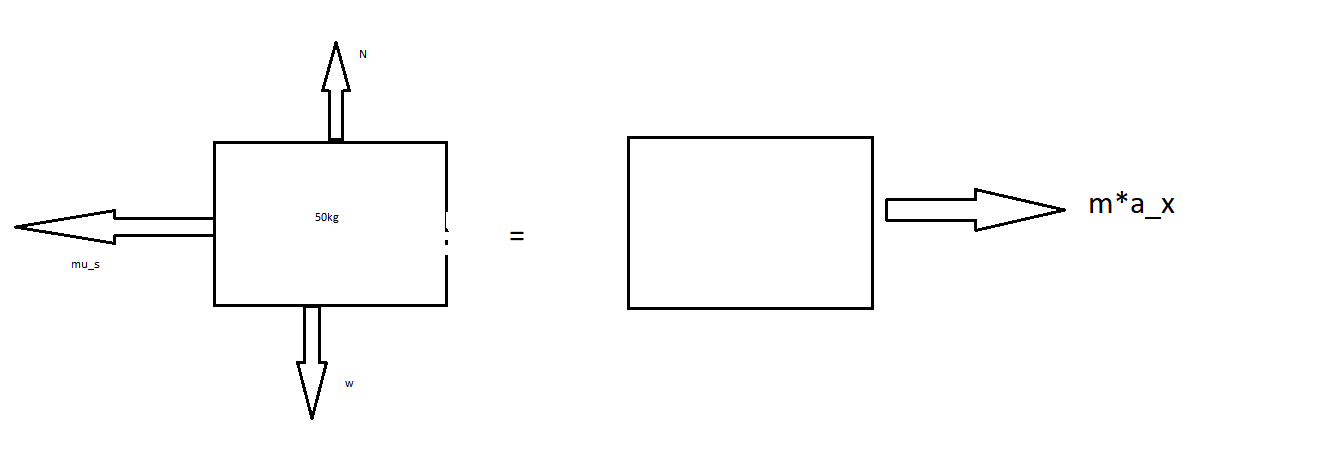

clear

m = 50;
v0 = 6;
vs = 0;
mu_k = 0.4;
grav = 9.81;

% Summen af kræfterne i x
displayFormula("F_x = m_box*a_x")
displayFormula("mu*m_box*g = m_box*a_x")
displayFormula("a_x = -mu * g")

displayFormula("v_x = a_x*t + v_0")
displayFormula("t = -v_0/a_x")

syms t
a_x = -mu_k*grav
v_x = a_x*t + v0 == vs;

t = vpa(solve(v_x, t),3)

s = 1/2*a_x*t^2 + v0*t;
s = vpa(s, 3)



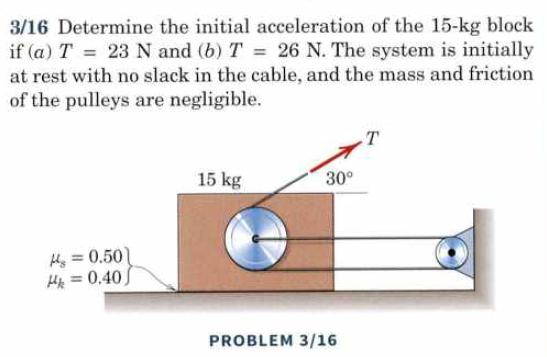

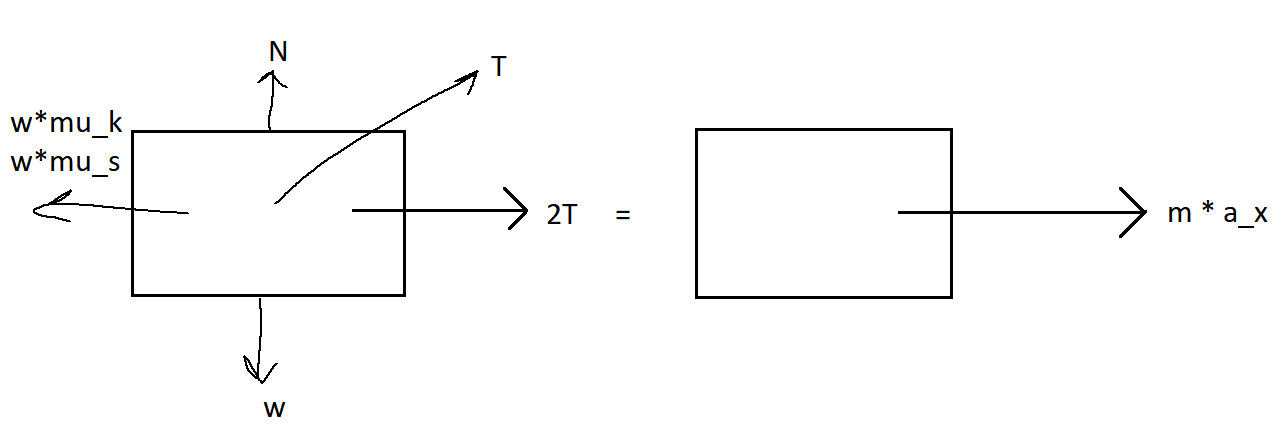

clear
format short

g = 9.81;
T = [23, 26];
m = 15;
theta = deg2rad(30);
mu_s = 0.5;
mu_k = 0.4;

% Kassens weight
w_y = m*g;

for i = 1:length(T)
    

    % Kræfter i y-retning
    syms N

    Ty = T(i)*sin(theta);

    Fy = -w_y + N + Ty == 0;

    N = vpa(solve(Fy, N),4)

    % Kræfter i x-retning
    syms F
    Tx = T(i)*(2 + cos(theta));

    Fx = -F + Tx == 0;
    F = vpa(solve(Fx, F),4)

    % Den statiske friktionskraft skal overgås før kassen bevæger sig
    F_statisk = mu_s * N; % Newton
    F_statisk = vpa(F_statisk, 4) % Newton


    if F > F_statisk
        F_dyn = mu_k * N;
        F_dyn = vpa(F_dyn, 3)

        syms a_x

        Fx = -F_dyn + Tx == m*a_x;
          
        a_x = vpa(solve(Fx, a_x), 4)
        
        fprintf(['da F = %.2f N > F_statisk = %.2f N flytter kassen sig.\n' ...
            'Det giver anledning til en acceleration a_x = %.2f m/s^2'], F, F_statisk, a_x)

    else
        fprintf('da F = %d N < F_statisk = %d N flytter kassen sig ikke.\n', F, F_statisk)
    end
    
end


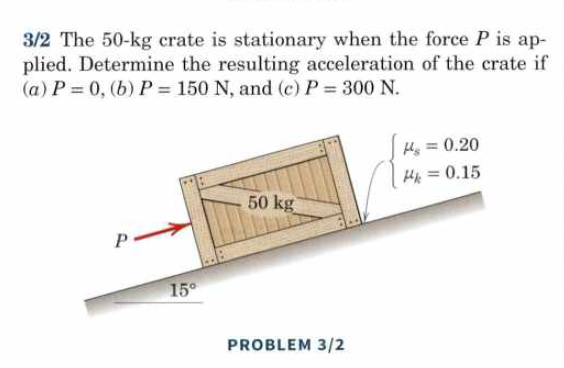

clear
format short

g = 9.81;
P = [0, 150, 300];
m = 50;
theta = deg2rad(15);
mu_s = 0.2;
mu_k = 0.15;

w_y = m*g*cos(theta);
w_x = m*g*sin(theta);


syms N
Fy = N - w_y == 0;
N = vpa(solve(Fy, N), 4)

$$N = 473.8$$


F_statisk = mu_s * N;
F_statisk = vpa(F_statisk, 4)

$$F\_statisk = 94.76$$


F_dyn = mu_k * N;


for i = 1:length(P)
    syms F
    Fx = P(i) - w_x + F == 0;
    F = vpa(solve(Fx, F), 4);

    if F > F_statisk
        disp("Bevægelse nedad")
        syms a_x
        Fx = F_dyn - w_x == m*a_x;
        a_x = vpa(solve(Fx, a_x), 4)
        fprintf("%.2f > %.2f", F, F_statisk)
        
    elseif abs(F) < F_statisk
        disp("Ingen bevægelse")
        fprintf("|%.2f| < %.2f", F, F_statisk)

    elseif abs(F) > F_statisk
        disp("Bevægelse opad")
        syms a_x
        Fx = P(i) - F_dyn - w_x == m*a_x;
        a_x = vpa(solve(Fx, a_x), 4)
        fprintf("|%.2f| > %.2f", F, F_statisk)

    end
end

Bevægelse nedad


$$a\_x = -1.118$$

126.95 > 94.76

Ingen bevægelse


|-23.05| < 94.76

Bevægelse opad


$$a\_x = 2.04$$

|-173.05| > 94.76

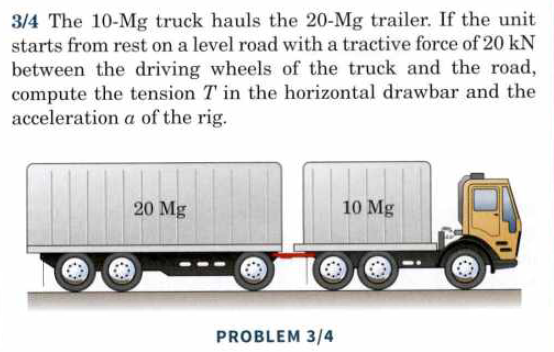

clear
displayFormula("F = ma")

$$F=\mathrm{ma}$$


F = 20000; % kN
m1 = 10e3; % gram
m2 = 20e3; % gram

m = m1+m2;

syms a

eq = F == m*a;
a = vpa(solve(eq, a), 3)

$$a = 0.667$$


% Tension i kabel

T = m2 * a;
T = vpa(T, 4)

$$T = 13330.0$$